# Taller 8 - Compensador en adelanto

clc, clear all, close all;

### Características del motor dc

% Especificaciones de desempeño
Mp  = 0.10;   
tss = 1;         %[s]
% Parámetros eléctricos
Ra = 0.635;      % R[Ohm]
La = 0.0883;     % L[H]
% Constantes del motor
Ki = 9.43e-3;    % [Nm/A]
Kb = 1010;       % [rpm/V]
% Parámetros mecánicos
Jm = 330;        % [kg·m^2]
Bm = 1e-3;       % [N·m·s]

#### Funcion de transferencia

num = [Ki/(La*Jm)];
den = [1 Bm/Jm+Ra/La (Ra*Bm+Ki*Kb)/(La*Jm)];

Gs = tf(num, den)

Gs =
 
        0.0003236
  ----------------------
  s^2 + 7.191 s + 0.3269
 
Continuous-time transfer function.
Model Properties


#### Polos

polos = pole(Gs)

polos =    -7.1457
   -0.0457


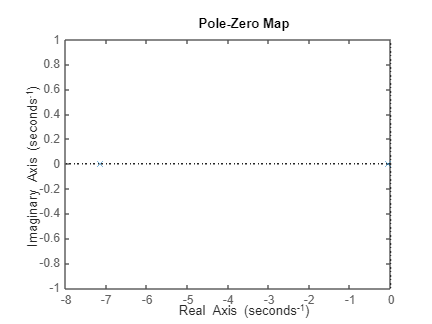


figure()
pzmap(Gs)

GRAFICAS: RESPUESTA AL IMPULSO Y LGR

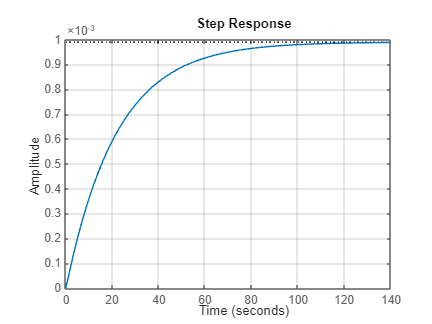

figure()
step(Gs)
grid on;

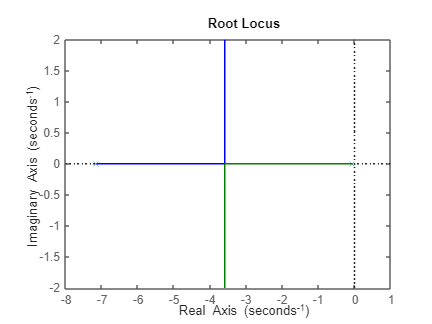

figure()
rlocus(Gs)

#### Compensación del modelo

zeta = log(1/Mp)/sqrt(pi^2+log(1/Mp)^2)

zeta = 0.5912

wn = 4/(tss*zeta)

wn = 6.7664


num1 = wn^2;
den1 = [1 2*zeta*wn wn^2];
Gs1 = tf(num1, den1)

Gs1 =
 
        45.78
  -----------------
  s^2 + 8 s + 45.78
 
Continuous-time transfer function.
Model Properties



raices_den1 = roots(den1)

raices_den1 =   -4.0000 + 5.4575i
  -4.0000 - 5.4575i


#### Graficar Polos del proceso original y polos de la respuesta deseada

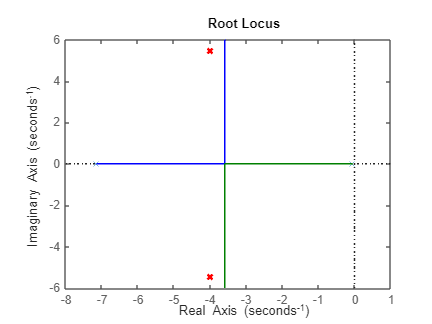

figure
rlocus(Gs)
hold on;  % Superponer graficos
plot(real(raices_den1), imag(raices_den1), 'rx', 'LineWidth', 2);
ylim([-6,6])
hold off;

#### Diseño del compensador en adelanto

### $G_c (s)=K_c \frac{s+z}{s+p}$  <= $G_{1c} (s)=\frac{s+z}{s+p}$

### pendiente: $m=\frac{y_2 -y_1 }{x_2 -x_1 }=\frac{\textrm{Im}(s_d )}{\textrm{Re}(s_d )-p_{\textrm{original}} }$ 

#### **angulo: **$\theta_1 =180^{\circ } +\arctan (m)\;\;;\;$$\theta_4 =180^{\circ } -\theta_1$

#### ubicacion del polo del compensador: $p_c =\textrm{Re}(s_d )-\frac{\textrm{Im}(s_d )}{\tan (\theta_4 )}$

m = (imag(raices_den1(1))-0)/(real(raices_den1(1))-polos(2))

m = -1.3802

theta1 = 180 + rad2deg(atan(m))

theta1 = 125.9253

theta4 = 180 - theta1

theta4 = 54.0747

p = real(raices_den1(1))-(imag(raices_den1(1))/tand(theta4)) % Polo Compensado

p = -7.9543

z = polos(1)  % Cero compensado

z = -7.1457


num2 = [1 -z];
den2 = [1 -p];
G1c = tf(num2, den2)

G1c =
 
  s + 7.146
  ---------
  s + 7.954
 
Continuous-time transfer function.
Model Properties



% Sistema compensado (sin Kc)
G1col = series(G1c, Gs)  % Open loop

G1col =
 
      0.0003236 s + 0.002312
  -------------------------------
  s^3 + 15.15 s^2 + 57.53 s + 2.6
 
Continuous-time transfer function.
Model Properties


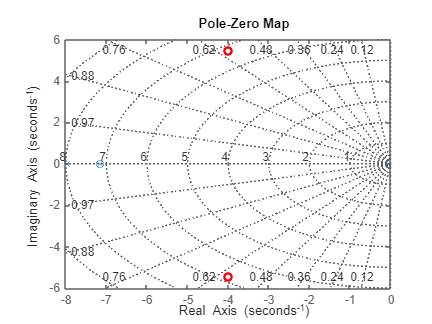

figure()
pzplot(G1col)
hold on;
plot(real(raices_den1), imag(raices_den1), 'ro', 'LineWidth', 2, 'DisplayName', 'Polos Deseados');
grid on; hold off;

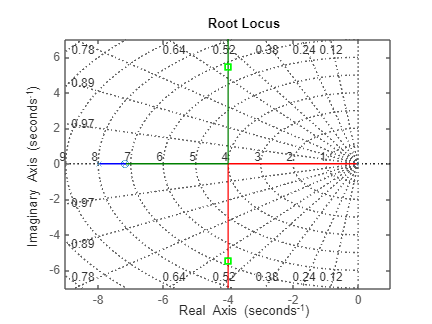


figure()
rlocus(G1col)
hold on;  % Superponer graficos
plot(real(raices_den1), imag(raices_den1), 'gs', 'LineWidth', 2, 'DisplayName', 'Objetivo');
grid on; ylim([-7,7])

#### Calculando $K_c$

Hs = Kb

Hs = 1010

G_s = G1c * Gs * Hs;
Kc = 1 / abs(evalfr(G_s, raices_den1(1)))

Kc = 138.9612

#### Compensador completo (Con $K_c$)

Gcol = Kc * G1c;           % Compensador completo (open loop)
Gccl = feedback(Gcol * Gs, Hs); % Compensador completo (close loop)
pole(Gccl)

ans =   -7.1457 + 0.0000i
  -4.0000 + 5.4575i
  -4.0000 - 5.4575i



[y, t] = step(Gccl);
[val_pico, idx] = max(y);

Graficas finales

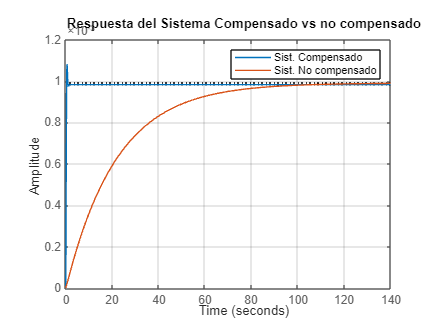

figure()
step(Gccl)
hold on;
step(Gs)
grid on; 
title('Respuesta del Sistema Compensado vs no compensado');
legend("Sist. Compensado", "Sist. No compensado");

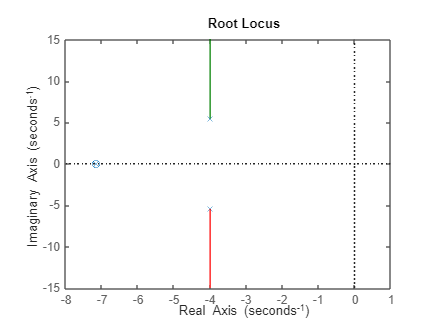


figure()
rlocus(Gccl)

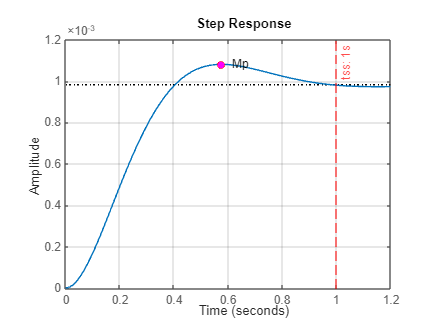


figure()
step(Gccl)
grid on; hold on;
xline(tss, '--r', 'tss: 1s');
plot(t(idx), val_pico, 'ro', 'MarkerFaceColor', 'm');
text(t(idx), val_pico, '   Mp');